# Decentralized OPF

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:\Users\", localUsername, "\Documents\documents_general\dablab_files\DOPF_1Phase_dablab\"))
    addpath('functions\')
end
addDirectories;

clearVariables(clearVars);

start = tic;
    
systemName = 'ieee123'

systemName = 'ieee123'

numAreas = 4

numAreas = 4

systemDataFolder = strcat("rawData/", systemName, "/numAreas_", num2str(numAreas), "/");

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
N = max(actualBusNums);

loss_min = true;   % CVR  = 0, Loss minimization = 1;
itrMax = 20; %Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
eps = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = true;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = true;
saveSimulationResults = true;
displaySimulationResultPlots = true;
saveSimulationResultPlots = true;

CVR = [0; 0]; %as opposed to [0.6; 3.0]

load_mult = 1;
gen_mult = 1;

verbose = true;
V_min = 0.95;
V_max = 1.05;

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  %2.4018

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parentArea = CBTable.parentArea(relationshipNum);
    isLeaf(parentArea, 1) = 0;
    childArea = CBTable.childArea(relationshipNum);
    isRoot(childArea, 1) = 0;
    numChildAreas(parentArea) = numChildAreas(parentArea) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);
S_allRelationships = CBTable.S_childArea;

S_parent = zeros(numAreas, 1);
S_child = zeros(N, numAreas);
v2_parent = 1.03^2*ones(numAreas, 1);
v2 = zeros(N, numAreas);
qD_Full_Areas = zeros(N, numAreas);
N_Areas = zeros(numAreas, 1);

#### Start with the algorithm

Plotting for Area 1:
This area has only the substation as its 'parent area'.
This area has 2 child areas, which include the Areas: Area 2 and Areas 3.


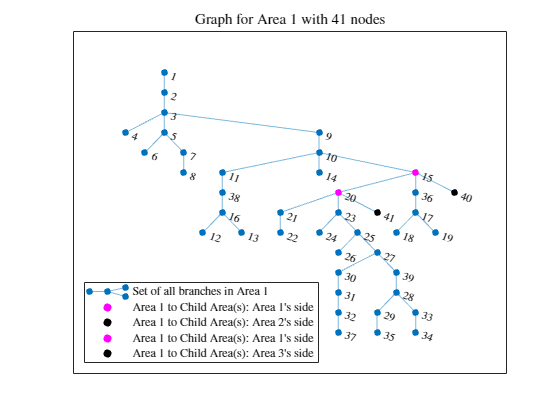

Plotting for Area 2:
This area's parent is Area 1.
This area has 1 child area: Area 4.


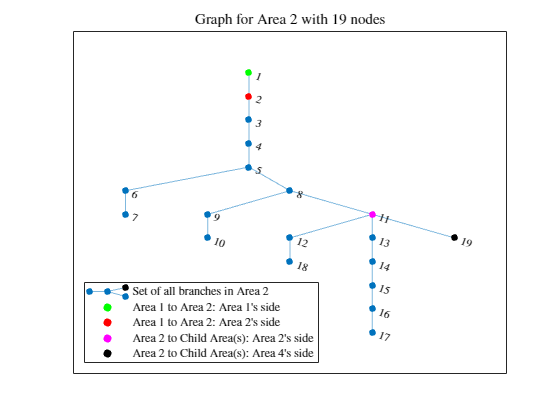

Number of DERs in Area 2 : 12
branchTable = 

table = 18×2 table
    fbus    tbus
    ____    ____

      1       2 
      2       3 
      3       4 
      4       5 
      5       6 
      6       7 
      5       8 
      8       9 
      9      10 
      8      11 
     11      12 
     11      13 
     13      14 
     14      15 
     15      16 
     16      17 


Aeq = 

table =     1.0000   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0040         0         0         0         0         0         0         0         0         0         0         0 

beq = 

table =          0
    0.0087
    0.0087
         0
    0.0043
    0.0043
         0
    0.0043
    0.0043
    0.0043


lb = 

table = 1.0e+03 *

         0
   -1.5000
   -1.5000
   -1.5000
   -1.5000
   -1.5000
   -1.5000
   -1.5000
   -1.5000
   -1.5000


ub = 

table = 1.0e+03 *

    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000


Plotting for Area 3:
This area's parent is Area 1.
This area has no child areas.


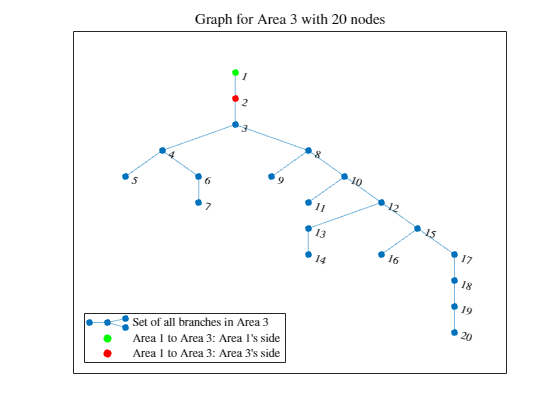

Plotting for Area 4:
This area's parent is Area 2.
This area has no child areas.


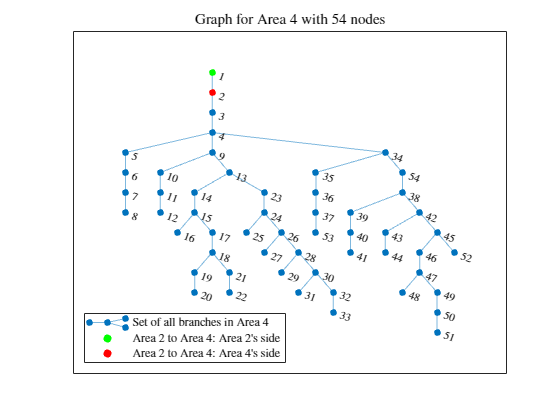

Still yet to converge after 0 iterations, continuing.
Still yet to converge after 1 iterations, continuing.
Still yet to converge after 2 iterations, continuing.
Still yet to converge after 3 iterations, continuing.
Still yet to converge after 4 iterations, continuing.


Converged in 5 iterations!


keepRunningIterations = 1;
itr = 0;
time_dist = zeros(itrMax, numAreas);
microIterationLosses = zeros(itrMax, numAreas);
R_max = zeros(itrMax, 1);

Se_iter = zeros(itrMax, numAreas);
V_iter = zeros(itrMax, N, numUniqueParents);

a = [0.25 0.05]; %coefficient for correction step

while keepRunningIterations
    for Area = 1 : numAreas

        v2_parent_Area = v2_parent(Area);
        S_childAreas = S_allRelationships(CBTable.parentArea == Area);

        isLeaf_Area = isLeaf(Area);
        isRoot_Area = isRoot(Area);
        numChildAreas_Area = numChildAreas(Area);

        [v2_Area, S_parent_Area, S_child_Area, qD_Full_Area,...
            microIterationLosses,  ...
            itr, time_dist, R, T_Area, N_Area, busDataTable_Area, branchDataTable_Area] = ...
            NL_OPF_dist(v2_parent_Area, S_childAreas, ...
            Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, ...
            numAreas, ...
            microIterationLosses, time_dist, itr, ...
            CBTable, 'verbose', verbose, 'saveToFile', true);
        
        N_Areas(Area) = N_Area;
        S_parent(Area) = S_parent_Area;
       
        qD_Full_Areas(1:N_Area, Area) = qD_Full_Area;
        v2(1:N_Area, Area) = v2_Area;   % Storing all the square of the node voltages
        S_child(1:N_Area, Area) = S_child_Area;   % Storing all the S flow of the Area
        
    end
    
    
    for relationshipNum = 1 : numRelationships

        parentArea = CBTable.parentArea(relationshipNum);
        childArea = CBTable.childArea(relationshipNum);
        parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
        parentAreaOutflowingPower = S_child(parentAreaConnectingBus - 1, parentArea);
        childAreaInflowingPower = S_parent(childArea);

        powerflowDifference = parentAreaOutflowingPower - childAreaInflowingPower;

        parentAreaConnectingBusVoltage = v2(parentAreaConnectingBus, parentArea);
        childAreaConnectingBusVoltage = v2_parent(childArea);

        voltageDifference = parentAreaConnectingBusVoltage - childAreaConnectingBusVoltage;

        R = [powerflowDifference; voltageDifference];
        
        if max(abs(R)) > R_max(itr+1)
            R_max(itr+1) = max(abs(R));
        end

    end
    
    if itr > itrMax
        fprintf("Didn't converge even in %d iterations, terminating.\n", itrMax);
        keepRunningIterations = 0;

    elseif R_max(itr+1) < eps
        fprintf("Converged in %d iterations!\n", itr);
        keepRunningIterations = 0;
        R_max = R_max(1:itr);

    else
        fprintf("Still yet to converge after %d iterations, continuing.\n", itr)
        %Communication-
        
        for relationshipNum = 1:numRelationships
            parentArea = CBTable.parentArea(relationshipNum);
            childArea = CBTable.childArea(relationshipNum);
            busParentTo = CBTable.conBus_parentAreaTo(relationshipNum);
            V_iter(itr+1, busParentTo, parentArea) = v2(busParentTo, parentArea) ;
            Se_iter(itr+1,childArea) = S_parent(childArea);

            if itr > 2
                v2_parent(childArea) = a(2)*V_iter(itr-1, busParentTo, parentArea)+...
                    a(1)*V_iter(itr, busParentTo, parentArea)+...
                    (1-sum(a))*v2(busParentTo, parentArea) ;

                S_allRelationships(relationshipNum) = a(2)*Se_iter(itr-1, childArea)+...
                    a(1)*Se_iter(itr, childArea)+...
                    (1-sum(a))*S_parent(childArea);
            else

                v2_parent(childArea) = v2(busParentTo, parentArea);
                S_allRelationships(relationshipNum) = S_parent(childArea);

            end

        end

        itr = itr + 1;

    end

end


N_ParentArea_Max = max(N_Areas(uniqueParents));
Se_iter = Se_iter(1:itr, :);
V_iter = V_iter(1:itr, 1:N_ParentArea_Max, uniqueParents);

Number of nodes in Area 1 = 41.
Number of nodes in Area 2 = 19.
Number of nodes in Area 3 = 20.
Number of nodes in Area 4 = 54.


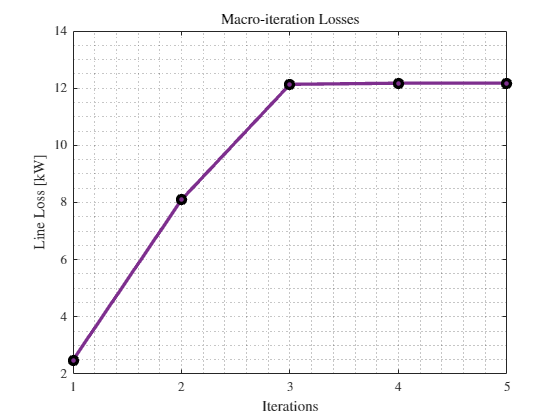

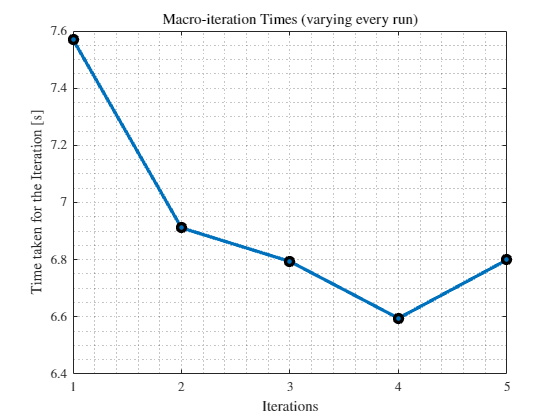

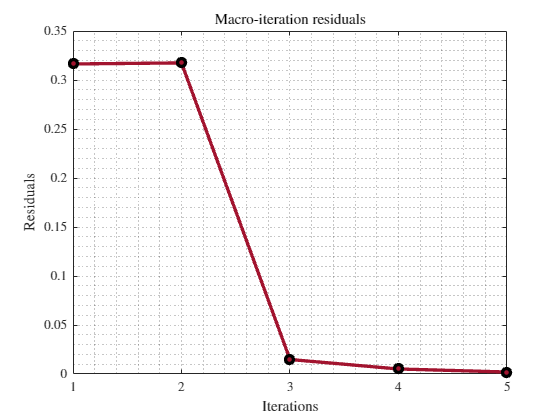

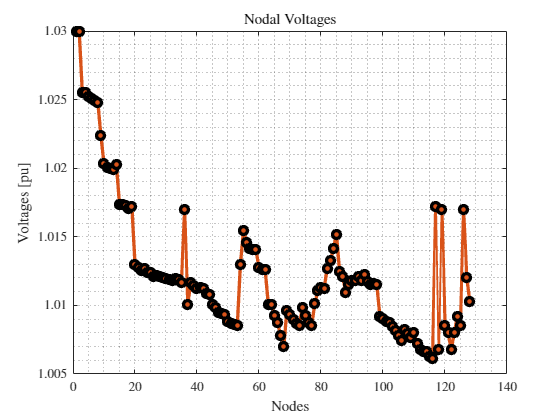

------------------------------------------------------------
Line Loss: 12.1778 kW
Substation Power: 768.2402 kW
Number of Iterations: 5
Time to Solve: 23.1222s
------------------------------------------------------------


postProcessResults(N, numAreas, N_Areas, isRoot, v2, actualBusNums, microIterationLosses, itr, time_dist, kVA_B, displaySimulationResultPlots, R_max, saveSimulationResultPlots, systemName, S_child, start, saveSimulationResults);